# **LiDAR SLAM**

addpath('./functions');

## Tracciamento della traiettoria

### Definizione della scena 

sceneName = 'LargeParkingLot';
[sceneImage, sceneRef] = helperGetSceneImage(sceneName);

### Selezione manuale dei waypoints

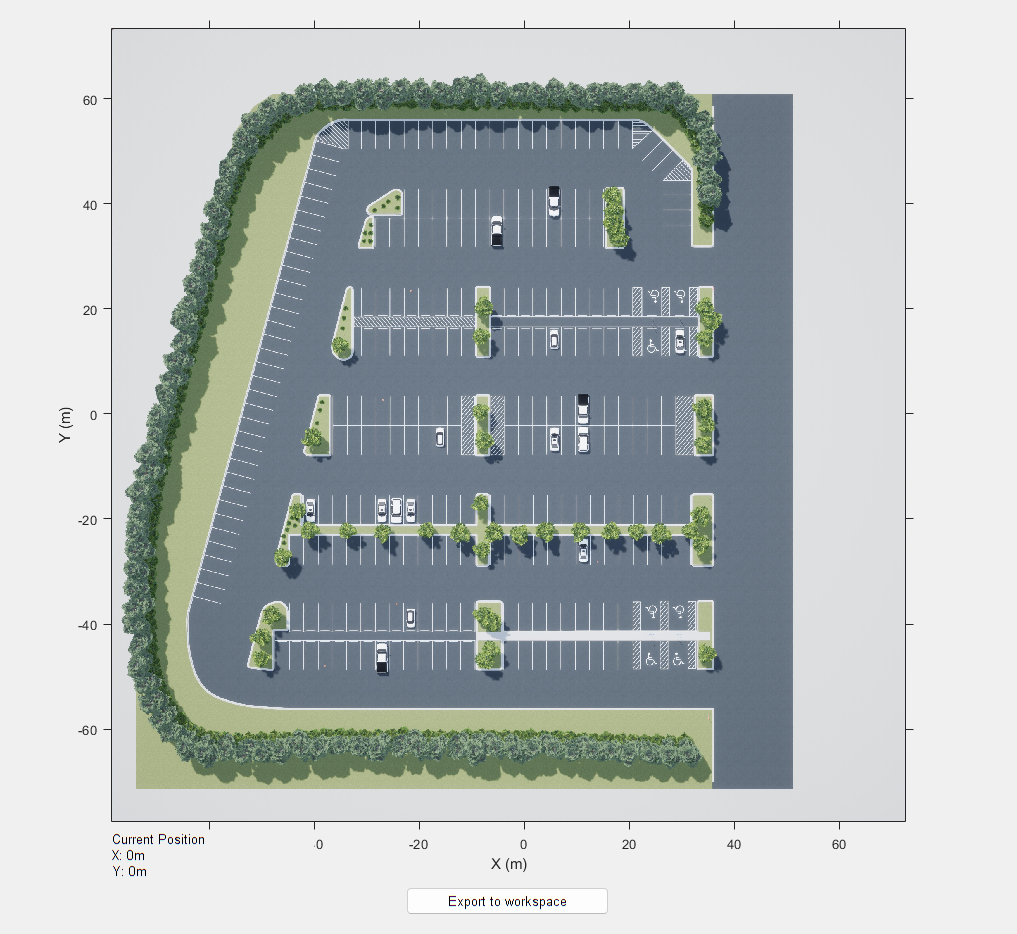

hFig = helperSelectSceneWaypoints(sceneImage, sceneRef);

### Genera percorso continuo 

numPoses = size(refPoses{1}, 1);
refDirections  = ones(numPoses,1);   % Movimento in avanti
numSmoothPoses = 20 * numPoses;      % Aumenta la densità delle pose

[smoothRefPoses,~,cumLengths] = smoothPathSpline(refPoses{1}, refDirections, numSmoothPoses);

## Simulazione

modelName = 'CustomLidarSLAM';
open_system(modelName);

% Parametri
simStopTime = 10;
set_param(modelName, 'StopTime', num2str(simStopTime));

timeVector = normalize(cumLengths, 'range', [0, simStopTime]);

% Variabili per Simulink
refPosesX = [timeVector, smoothRefPoses(:,1)];
refPosesY = [timeVector, smoothRefPoses(:,2)];
refPosesT = [timeVector, smoothRefPoses(:,3)];

### Estrazione dei dati LIDAR

lidarData = out.lidarScans.signals.values;  
numScans = size(lidarData, 4); % Numero totale di scansioni nel tempo

### Visualizzazione della scansione

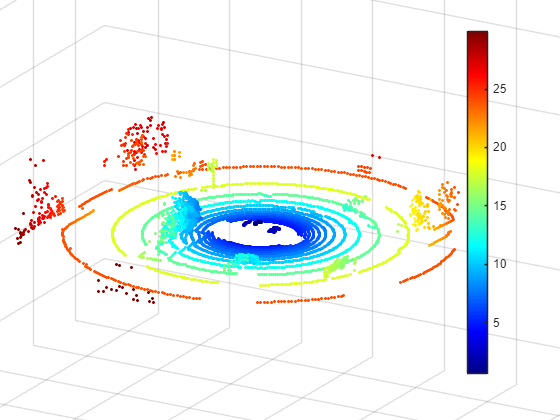

% Creazione della finestra di visualizzazione
figure;
hold on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Nuvola di punti LIDAR in tempo reale');
axis equal;
grid on;
colormap jet; % Imposta la mappa di colori per la distanza
view(30, 20); % Imposta la vista isometrica
camzoom(2); % Aumenta il fattore per avvicinarti di più

lidarValues = squeeze(lidarData(:, :, :, 1)); % (32x360x3) -> (N x 3)
points3D = reshape(lidarValues, [], 3); % Trasforma in (32*360, 3)

% Calcola la distanza dall'origine per ogni punto
distances = sqrt(sum(points3D.^2, 2)); 

% Creazione dell'oggetto scatter per aggiornamenti in tempo reale
scatterHandle = scatter3(points3D(:, 1), points3D(:, 2), points3D(:, 3), 5, distances, 'filled');
colorbar; % Aggiunge una legenda per il colore basato sulla distanza

% Loop per aggiornare la visualizzazione senza errori
for scanIndex = 2:numScans  
    lidarValues = squeeze(lidarData(:, :, :, scanIndex)); % (32x360x3)  
    points3D = reshape(lidarValues, [], 3); % (32*360, 3)

    % Calcola la distanza dall'origine
    distances = sqrt(sum(points3D.^2, 2)); 

    % Aggiorna la nuvola di punti con colore basato sulla distanza
    set(scatterHandle, 'XData', points3D(:, 1), ...
                       'YData', points3D(:, 2), ...
                       'ZData', points3D(:, 3), ...
                       'CData', distances); % Colore basato sulla distanza
    drawnow;
end

%hMapOnScene = helperSuperImposeMapOnSceneImage('LargeParkingLot',
%points3D); % da rivedere 

## Preprocessing dati LiDAR

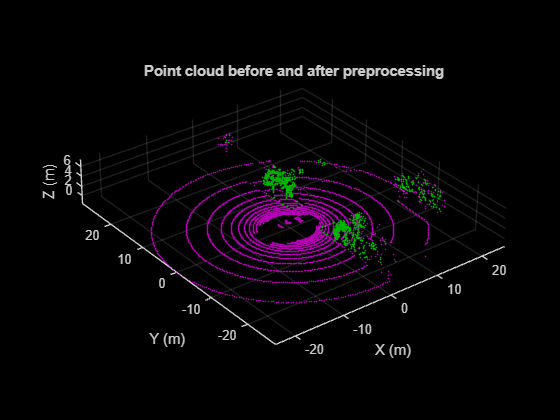

% Extract lidar data
ptCloudArr = helperPointClouds(out);

% Extract ground truth for the lidar data as an array of rigidtform3d objects
groundTruthPosesLidar = helperGetLidarGroundTruth(out);

ptCloud = ptCloudArr(1);

% Use the helper function to preprocess the point cloud
ptCloudProcessed = helperPreprocessPC(ptCloud);

% Visualize and compare the point cloud before and after preprocessing.
figure(Name="Processed Point Clouds",NumberTitle="off");
pcViewAxes = pcshowpair(ptCloud, ptCloudProcessed);
title("Point cloud prima e dopo il preprocessing");
xlabel(pcViewAxes,"X (m)");
ylabel(pcViewAxes,"Y (m)");
zlabel(pcViewAxes,"Z (m)");